# Solution to *Escape Velocity I* exercise

## Set parameters

M = 1.02e26;
R = 2.47e7;

## Call function

[r,Ve,g] = veandg(M,R);

## Plot results

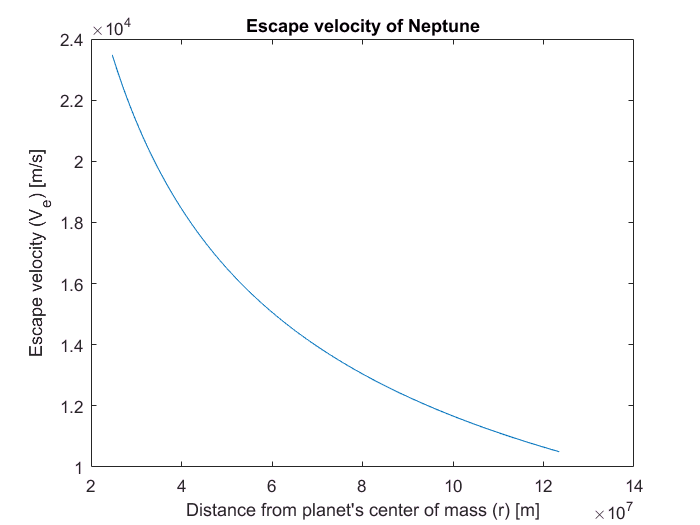

plot(r,Ve)
xlabel('Distance from planet''s center of mass (r) [m]')
ylabel('Escape velocity (V_e) [m/s]')
title('Escape velocity of Neptune')

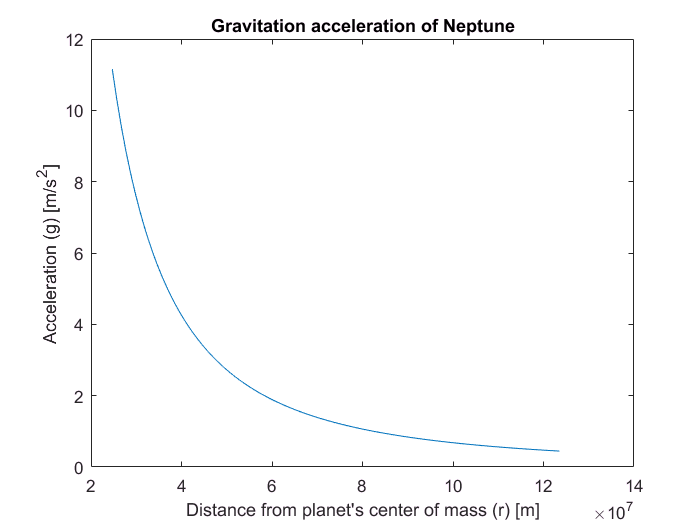


plot(r,g)
xlabel('Distance from planet''s center of mass (r) [m]')
ylabel('Acceleration (g) [m/s^2]')
title('Gravitation acceleration of Neptune')

## Local function

Calculate $$ and $$ according the the formulae

$V_e = \sqrt{\frac{2GM}{r}} $  and   $g = \frac{GM}{r^2}$

function [r,Ve,g] = veandg(M,R)
    r = linspace(R,5*R);    % Define vector of distances
    G = 6.673e-11;
    Ve = sqrt(2*G*M./r);
    g = G*M./(r.^2);
end